# Taller VI

### 09/05/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 3 y 4*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### Interpolación Segmentaria

Para el taller de esta semana se solucionan la primera parte (1), y de la segunda parte los ejercicios $6\;y\;8$ del taller 7, se propone el uso de los métodos cs y las propias herramientas de Matlab

**Parte 1) **Construcción de un Spline Cúbico

Consideramos los datos tabulados

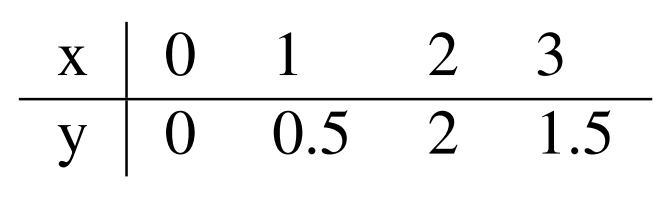

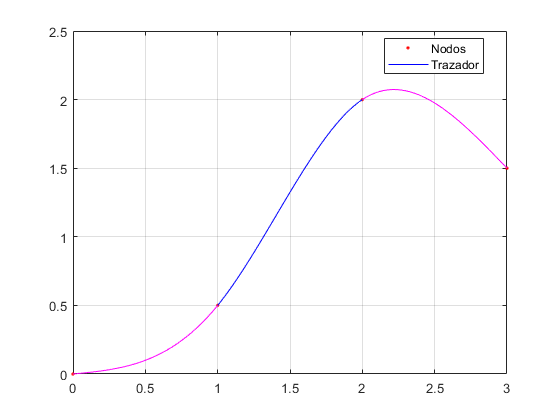

clear

X = 0:3;
Y = [0 .5 2 1.5];

% Spline Natural
CN = csnatural(X, Y);
GraficaCercha(X, Y, CN)
% Sujeto: f'(0) = -2, f'(3) = 10
CS = csfit(X, Y, -2, 10);
GraficaCercha(X, Y, CS)
% Curvatura en los extremos: f''(0) = -3, f''(3) = 3
CC = csconocido(X, Y, -10, 10);
GraficaCercha(X, Y, CC)
% Extrapolado
CE = csextrapolado(X, Y);

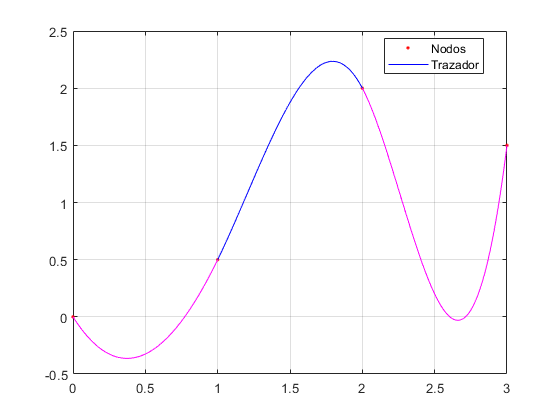

GraficaCercha(X, Y, CE)
% Terminación parabolica
CO = csconstante(X, Y);

GraficaCercha(X, Y, CO)

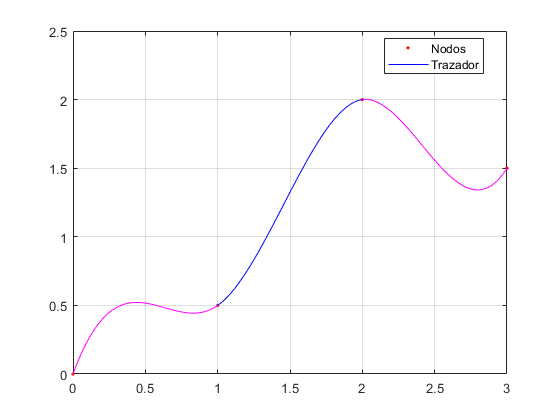

% Spline Conocido
clf('reset')

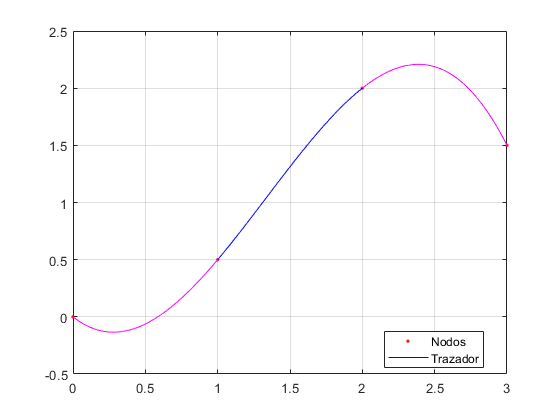

hold on
fplot(@(x) polyval(CO(1,:), x - X(1)), [X(1) X(2)], 'r')
fplot(@(x) polyval(CO(2,:), x - X(2)), [X(2) X(3)], 'g')

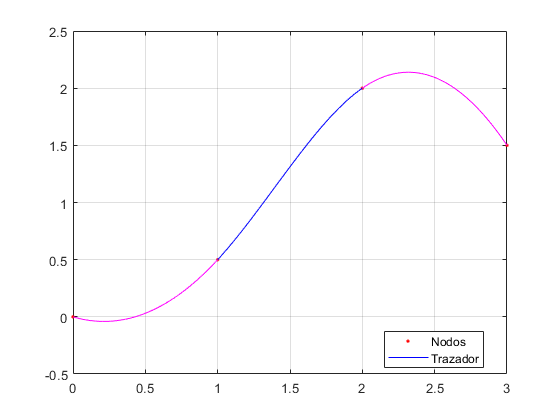

fplot(@(x) polyval(CO(3,:), x - X(3)), [X(3) X(4)], 'r')
grid on
hold off

**Parte 2) 6. **Determine si existen coeficientes $a,b,c\;y\;d$ de tal forma que la función:

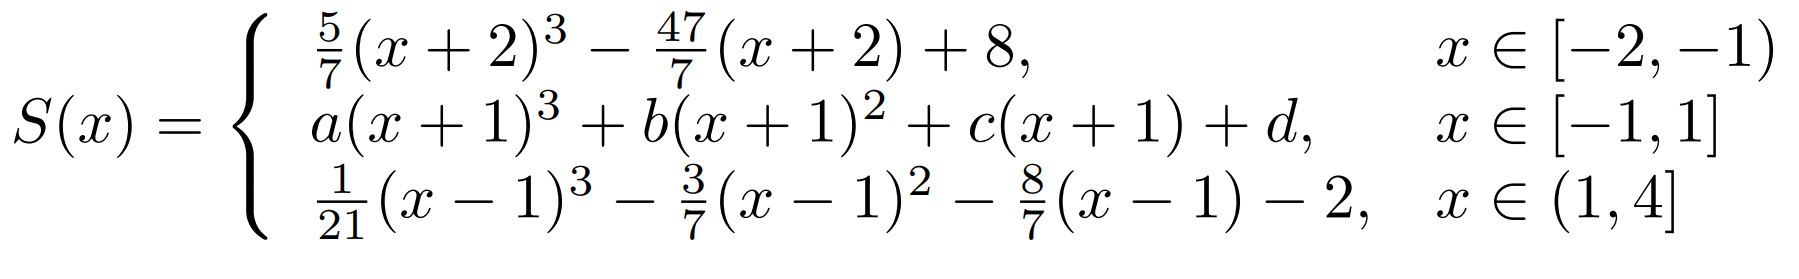

sea un spline cúbico en el intervalo $\left\lbrack -2,4\right\rbrack$. ¿Es un spline cúbico natural?

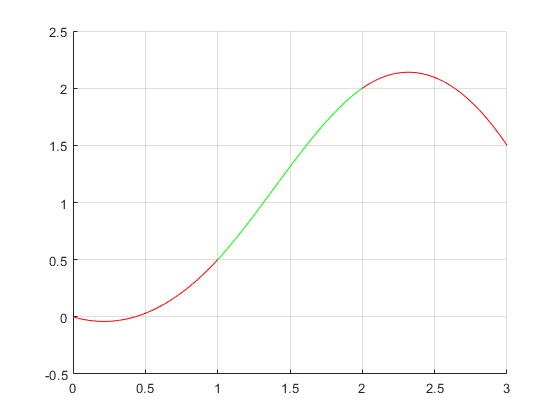

clear
syms S(x) a b c d

S1(x) = 5/7 * (x + 2)^3 - 47/7 * (x + 2) + 8;
S2(x) = a * (x + 1)^3 + b * (x + 1)^2 + c * (x + 1) + d;
S3(x) = 1/21 * (x - 1)^3 - 3/7 * (x - 1)^2 - 8/7 * (x - 1) - 2;


% Condición de continuidad
Eq1 = S1(-1) == S2(-1), Eq2 = S2(1) == S3(1)
dS1(x) = diff(S1);
dS2(x) = diff(S2);
dS3(x) = diff(S3);

% Condición de diferenciabilidad
Eq3 = dS1(-1) == dS2(-1), Eq4 = dS2(1) == dS3(1)
d2S1(x) = diff(dS1);
d2S2(x) = diff(dS2);
d2S3(x) = diff(dS3);

% Condición de Curvatura

$$Eq1 = 2=d$$

$$Eq2 = 8\,a+4\,b+2\,c+d=-2$$

Eq5 = d2S1(-1) == d2S2(-1), Eq6 = d2S2(1) == d2S3(1)
S = solve(Eq1, Eq2, Eq3, Eq4, Eq5, Eq6)
a = S.a, b = S.b, c = S.c, d = S.d
S2(x) = a * (x + 1)^3 + b * (x + 1)^2 + c * (x + 1) + d

Se hallan los valores de $a,b,c,d$, y se verifica que $S\left(x\right)$, se trata de un spline cúbico.

% Condición de Naturalidad
d2S1(-2), d2S3(4)

$$Eq3 = -\frac{32}{7}=c$$

$$Eq4 = 12\,a+4\,b+c=-\frac{8}{7}$$

**Parte 2) 8. **Indique si la función $S\left(x\right)$ dada por

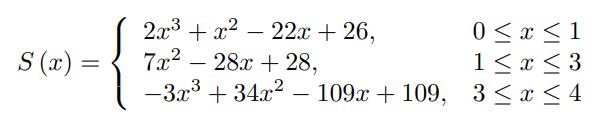

Es un spline cúbico natural para la tabla

clear

X = [0 1 3 4];
Y = [26 7 7 25];

C1 = [2 1 -22 26]; C2 = [0 7 -28 28]; C3 = [-3 34 -109 109]; % Coeficientes de los polinomios.

$$Eq5 = \frac{30}{7}=2\,b$$

$$Eq6 = 12\,a+2\,b=-\frac{6}{7}$$

S = struct with fields:
    a: [1×1 sym]
    b: [1×1 sym]
    c: [1×1 sym]
    d: [1×1 sym]


clf('reset')

$$a = -\frac{3}{7}$$

$$b = \frac{15}{7}$$

$$c = -\frac{32}{7}$$

$$d = 2$$

hold on

$$S2(x) = \frac{15\,{\left(x+1\right)}^{2}}{7}-\frac{32\,x}{7}-\frac{3\,{\left(x+1\right)}^{3}}{7}-\frac{18}{7}$$

fplot(@(x) polyval(C1, x), [X(1) X(2)], 'r')
fplot(@(x) polyval(C2, x), [X(2) X(3)], 'g')
fplot(@(x) polyval(C3, x), [X(3) X(4)], 'r')

$$ans = 0$$

$$ans = 0$$

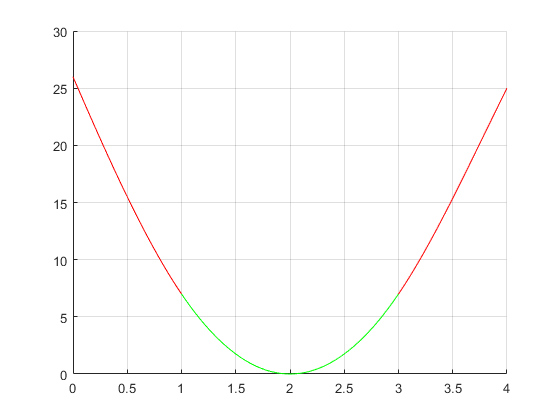

grid on
hold off
% Definimos el Spline
S1 = @(x) polyval(C1, x);
S2 = @(x) polyval(C2, x);
S3 = @(x) polyval(C3, x);

dC1 = polyder(C1); dC2 = polyder(C2); dC3 = polyder(C3); % Coeficientes de las derivadas

dS1 = @(x) polyval(dC1, x);
dS2 = @(x) polyval(dC2, x);
dS3 = @(x) polyval(dC3, x);

d2C1 = polyder(dC1); d2C2 = polyder(dC2); d2C3 = polyder(dC3); % Coeficientes de la curvatura

d2S1 = @(x) polyval(d2C1, x);
d2S2 = @(x) polyval(d2C2, x);
d2S3 = @(x) polyval(d2C3, x);


% Condición de Continuidad
S1(1) == S2(1), S2(3) == S3(3)
% Condición de Diferenciabilidad
dS1(1) == dS2(1), dS2(3) == dS3(3)
% Condición de Curvatura
d2S1(1) == d2S2(1), d2S2(3) == d2S3(3)
d2S1(0), d2S3(4)

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = 2

ans = -4

$S\left(x\right)$, no se trata de un Spline Cúbico Natural.

`function S = csline(X,Y)`

`% Entrada   - X es el vector de abscisas  1 x n`

`%           - Y es el vector de ordenadas 1 x n`

`% Salida    - S las filas de S son los coeficientes `

`%           para los interpolantes (trazadores) lineales `

`%  METODOS NUMERICOS: 2022-01S`

`%  La rutina se desarrolla en el taller`

`%  Semana 8: 16/05/2022`

`%  Alejandro Luján Rocha`

`%  Estudiante de Ing Física`

`%  alujan@unal.edu.co`

`% Definición de elementos necesarios`

`H = diff(X);`

`N = length(X);`

`% Definimos la matriz de iteración`

`T = -1 * eye(N) + diag( ones(N-1, 1) , 1);`

`T = T(1:N-1, :);`

`% Encontramos la solución de iteración, y limpiamos los datos.`

`B = T * Y';`

`B = B ./ H';`

`S = [ B, Y(1:N-1)' ];`